load ('CNC110X69-5.mat');
load ('Samsung_30Q_18650_pack.mat');

sim_time = 10;

% Maximum duty cycle that can be achieved:
D_max = 1 - pv_data.Vmpp/Ubat_nom; % MPP mode of operation

% Switching frequency:
f = 1 * 10^5; % [Hz]
T = 1/f;

% Passive elements:
RL = 10 * 10^-3;
curr_ripple = 0.4

curr_ripple = 0.4000

% L = (pv_data.Vmpp * D_max)/(curr_ripple * pv_data.Impp * f);
L = 100 * 10^-6;
Rt = 10000;
Cu = 50 * 10^-3;
volt_ripple = 0.1;
% Ci = 6 * 10^-6;
Ci = (Ubat_charged * D_max)/(0.3 * Ubat_charged * Ru * f);
Ci = 10 * Ci;
Cbat = Qbat_tot/(Ubat_charged - Ubat_cut_off);

% CCM limit detection sample time:
% Ts = 1 * 10^(-4);

% Input/output voltage and CCM limit:
% Uin = 5; % [V]
% Uout = 14; % [V]

% CCM: D <= limit
% D1 = round(limit - 0.1, 1);
% D2 = 0.8;

## Steady state (point of maximum power):

% Same for both:
Ipv0 = pv_data.Impp;
Upv0 = pv_data.Vmpp;

% CCM steady state:
Ubat0_ccm = Ubat_nom;
IL0_ccm = Ipv0;
D0_ccm = (Ubat0_ccm + RL * IL0_ccm - Upv0)/Ubat0_ccm;
I10_ccm = (1 - D0_ccm) * IL0_ccm;
Uoc0_ccm = (Ru + Rt)/Rt * Ubat0_ccm - Ru*I10_ccm;

% DCM steady state:
Ubat0_dcm = Ubat_charged;
Uoc0_dcm = Ubat0_dcm;
IL0_dcm = Ipv0;
% IL0_dcm = (D0_dcm^2 * T * Upv0 * Ubat0)/(2 * L * (Ubat0 - Upv0));
% D0_dcm = sqrt((IL0_dcm * 2 * L * (Ubat0_dcm - Upv0))/(T * Upv0 * Ubat0_dcm));
D0_dcm = D_max;
I10_dcm = (Upv0 * IL0_dcm)/(Ubat0_dcm);
Uoc0_dcm = (Ru + Rt)/Rt * Ubat0_dcm - Ru*I10_dcm;

## State space and Transfer functions:

% CCM matrices:
A_ccm = sym('a', [3, 3]);
B_ccm = sym('b', [3, 2]);
C_ccm = eye(3);
D_ccm = zeros(3,2);

% DCM matrices:
A_dcm = sym('a', [2, 2]);
B_dcm = sym('b', [2, 2]);
C_dcm = eye(2);
D_dcm = zeros(2,2);

subs_list_ccm = {
    A_ccm(1, 1), -RL/L;
    A_ccm(1, 2), 1/L;
    A_ccm(1, 3), (D0_ccm-1)/L;
    A_ccm(2, 1), -1/Cu;
    A_ccm(2, 2), -(Ipv0)/(Cu*Upv0);
    A_ccm(2, 3), 0;
    A_ccm(3, 1), (1-D0_ccm)/Ci;
    A_ccm(3, 2), 0;
    A_ccm(3, 3), 0;
    B_ccm(1, 1), Ubat0_ccm/L;
    B_ccm(1, 2), 0;
    B_ccm(2, 1), 0;
    B_ccm(2, 2), 0;
    B_ccm(3, 1), -IL0_ccm/Ci;
    B_ccm(3, 2), -1/Ci
};

subs_list_dcm = {
    A_dcm(1, 1), -1/Cu*((Ubat0_dcm^2*D0_dcm^2*T)/((Ubat0_dcm-Upv0)^2*2*L) + Ipv0/Upv0);
    A_dcm(1, 2), (Upv0^2*D0_dcm^2*T)/((Ubat0_dcm-Upv0)^2*2*L*Cu);
    A_dcm(2, 1), 1/Ci*((Upv0*Ubat0_dcm*D0_dcm^2*T)/((Ubat0_dcm-Upv0)^2*2*L) + IL0_dcm/Ubat0_dcm);
    A_dcm(2, 2), -1/(Ci*Ubat0_dcm)*((Upv0^3*D0_dcm^2*T)/((Ubat0_dcm-Upv0)^2*2*L) + (Upv0*IL0_dcm)/Ubat0_dcm);
    B_dcm(1, 1), -(Upv0*Ubat0_dcm*D0_dcm*T)/((Ubat0_dcm-Upv0)*L*Cu);
    B_dcm(1, 2), 0;
    B_dcm(2, 1), (Upv0^2*D0_dcm*T)/((Ubat0_dcm-Upv0)*L*Ci);
    B_dcm(2, 2), -1/Ci
};

A_ccm = double(subs(A_ccm, subs_list_ccm(:,1), subs_list_ccm(:,2)));
B_ccm = double(subs(B_ccm, subs_list_ccm(:,1), subs_list_ccm(:,2)));
A_dcm = double(subs(A_dcm, subs_list_dcm(:,1), subs_list_dcm(:,2)));
B_dcm = double(subs(B_dcm, subs_list_dcm(:,1), subs_list_dcm(:,2)));

[CCM_tf_d_num, CCM_tf_d_den] = ss2tf(A_ccm, B_ccm, C_ccm, D_ccm, 1);
[CCM_tf_i1_num, CCM_tf_i1_den] = ss2tf(A_ccm, B_ccm, C_ccm, D_ccm, 2);
[DCM_tf_d_num, DCM_tf_d_den] = ss2tf(A_dcm, B_dcm, C_dcm, D_dcm, 1);
[DCM_tf_i1_num, DCM_tf_i1_den] = ss2tf(A_dcm, B_dcm, C_dcm, D_dcm, 2);


% Ignore:
% CCM_tf = tf(ss(A_ccm, B_ccm, C_ccm, D_ccm));
% DCM_tf = tf(ss(A_dcm, B_dcm, C_dcm, D_dcm));
% CCM_tf_sym = C * inv((s*eye(3) - A)) * B + D
% CCm_tf_num = subs(CCM_tf_sym, subs_list_ccm);

% [b_ccm, a_ccm] = ss2tf(A_ccm, B_ccm, C_ccm, D_ccm)


## Display transfer functions:

syms s
% 
% pretty(poly2sym(CCM_tf_d_num(2,:), s) / poly2sym(CCM_tf_d_den(:).', s));
% 
% vpa(poly2sym(CCM_tf_d_num(2,:), s) / poly2sym(CCM_tf_d_den(:).', s), 5)

C_ccm_alt = [1, 0, 0];
D_ccm_alt = zeros(1, 2);
C_dcm_alt = [0, 1];
D_dcm_alt = zeros(1, 2);

sys_ccm = ss(A_ccm, B_ccm, C_ccm_alt, D_ccm_alt);
G = tf(sys_ccm)

G =
 
  From input 1 to output:
   1.08e05 s^2 + 1.332e05 s + 2.52e04
  -------------------------------------
  s^3 + 101 s^2 + 2.467e05 s + 4.665e04
 
  From input 2 to output:
          1.008e05 s + 1.008e05
  -------------------------------------
  s^3 + 101 s^2 + 2.467e05 s + 4.665e04
 
Continuous-time transfer function.



[num_ccm, den_ccm] = tfdata(G, 'v');
poly2sym(num_ccm{1}, s)/poly2sym(den_ccm{1}, s)

$$ans = \frac{\frac{3710851743744001\,s^{2}}{34359738368}+\frac{1144204279920993\,s}{8589934592}+\frac{6927723007519777}{274877906944}}{s^{3}+101\,s^{2}+\frac{8478221412718279\,s}{34359738368}+\frac{6411351061125939}{137438953472}}$$


num = num_ccm{1};  % Use curly braces!
den = den_ccm{1};

num_norm = num / den(1);  % divide both by leading coefficient
den_norm = den / den(1);

disp('TF d -> Upv (CCM):');

TF d -> Upv (CCM):


poly2sym(num_norm, s)/poly2sym(den_norm, s)

$$ans = \frac{\frac{3710851743744001\,s^{2}}{34359738368}+\frac{1144204279920993\,s}{8589934592}+\frac{6927723007519777}{274877906944}}{s^{3}+101\,s^{2}+\frac{8478221412718279\,s}{34359738368}+\frac{6411351061125939}{137438953472}}$$

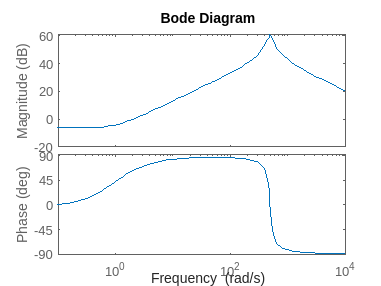


bode(G(1))

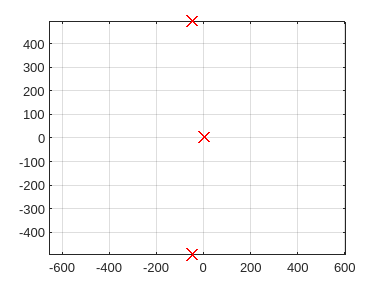

poles = roots(den);
figure()
plot(real(poles), imag(poles), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
grid on;
axis equal;

## Limit:

% limit = (Ubat0_ccm - Upv0)/Ubat0_ccm;
% Input step function parameters:
step_time = 0.002;
D1 = 0.6

D1 = 0.6000

D2 = 0.61

D2 = 0.6100


Rccm_mpp = (Upv0/Ipv0)/((1-D2)^2) - RL

Rccm_mpp = 131.4824


% Critical resistance:
% Rcrit = (2*L)/(T*Dcrit*(1-Dcrit)^2) * (Ubat0_ccm/Upv0)
Rcrit = (2*L)/(D2^2*T) * (Ubat0_ccm/Upv0)^2

Rcrit = 673.3674

## Baterija

% clear all;
% 
% % number of cells in series:
% s = 3;
% % number of parallel branches:
% p = 2;
% 
% % Internal resistance of a single cell:
% R = 0.0026; % ohm
% % Total internal resistance:
% Ru = (p/(s * R))^-1; % ohm
% 
% Ubat_nom = 3.6 * s; % [V]
% Ubat_charged = 4.2 * s; % [V]
% Ubat_discharge = 2.5 * s; % [V]const
% Ubat_cut_off = 2.5 * s; % [V]
% Ibat_max_discharge = 10 * p; % [A]
% Ibat_rated_charge = 1.5 * p; % [A]
% Ibat_max_charge = 4 * p; % [A]
% 
% Qbat = 3000; % [mAh]
% Qbat_tot = Qbat/1000 * p * 3600; % [C]
% Ebat_max = (Ubat_charged * Qbat_tot); % [Ws]
% Ebat_min = (Ubat_cut_off * Qbat_tot); % [Ws]
% 
% save Samsung_30Q_18650_pack;
% 
% clear all;